# Power Method and Rayleigh Quotient to approximate eigenvectors/eigenvalues

Power Method (power iteration) algorithm for any square matrix $A$:

- Start with any non-zero vector $x_0$ and divide by its length to make it a unit vector.

- For $k\ge 1,{\;x}_k =Ax_{k-1}$. Alternatively, $x_k =A^k x_0 \ldotp$

- Normalizing the previous formula yields: $x_k =\frac{Ax_{k-1} }{\left\|Ax_{k-1} \right\|}$.

- $x_k$ will converge to a dominant eigenvector of $A\ldotp$

Rayleigh Quotient for any unit vector $x$ ($\left\|x\right\|=1$) and any square matrix $A$:

- $R\left(A,x\right)=x^T \textrm{Ax}$. 

- $R\left(A,x\right)$ will converge to a dominant eigenvalue of $A$, if $x$ is a dominant unit eigenvector.

 **Reflect**.

- Why will $R\left(A,x\right)$ converge to a dominant eigenvalue of $A$, if $x$ is a dominant unit eigenvector? Why is the the Rayleigh Quotient defined like that?

Now, let's see how these two concepts work in practice. Let's start by generating a random 2x2 matrix $A$ and a random non-zero vector $x_0$. Check the MathWorks documentation page for [randi](https://www.mathworks.com/help/matlab/ref/randi.html).

A=randi(3,2,2)

A =      3     1
     3     3


x0=randi(3,2,1)

x0 =      2
     1


We will now normalize vector $x_0$ to be a unit vector. Check the MathWorks documentation page for [norm](https://www.mathworks.com/help/matlab/ref/norm.html).

x0=x0/norm(x0)

x0 =     0.8944
    0.4472


We'll now create a loop that implements the power method. Check the MathWorks documentation page for [while](https://www.mathworks.com/help/matlab/ref/while.html). We'll run the iteration 5 times. You can do the same with a [for](https://www.mathworks.com/help/matlab/ref/for.html) loop. A while loop simply allows us to run the iteration until a certain condition is met.

n=1; % creating a loop counter
x=x0; % storing the random non-zero vector in x
while n<6
    x=(A*x)/norm(A*x);  % running the power iteration for n=1,2,3,4,5
    n=n+1;
end
x % displaying the output

x =     0.5006
    0.8657


Let's first visualize the power method outcome. We'll plot the inital vector $x_0$ versus $Ax_0$. Check the MathWorks documentation pages for [quiver](https://www.mathworks.com/help/matlab/ref/quiver.html), [hold](https://www.mathworks.com/help/matlab/ref/hold.html) and [legend](https://www.mathworks.com/help/matlab/creating_plots/add-legend-to-graph.html).

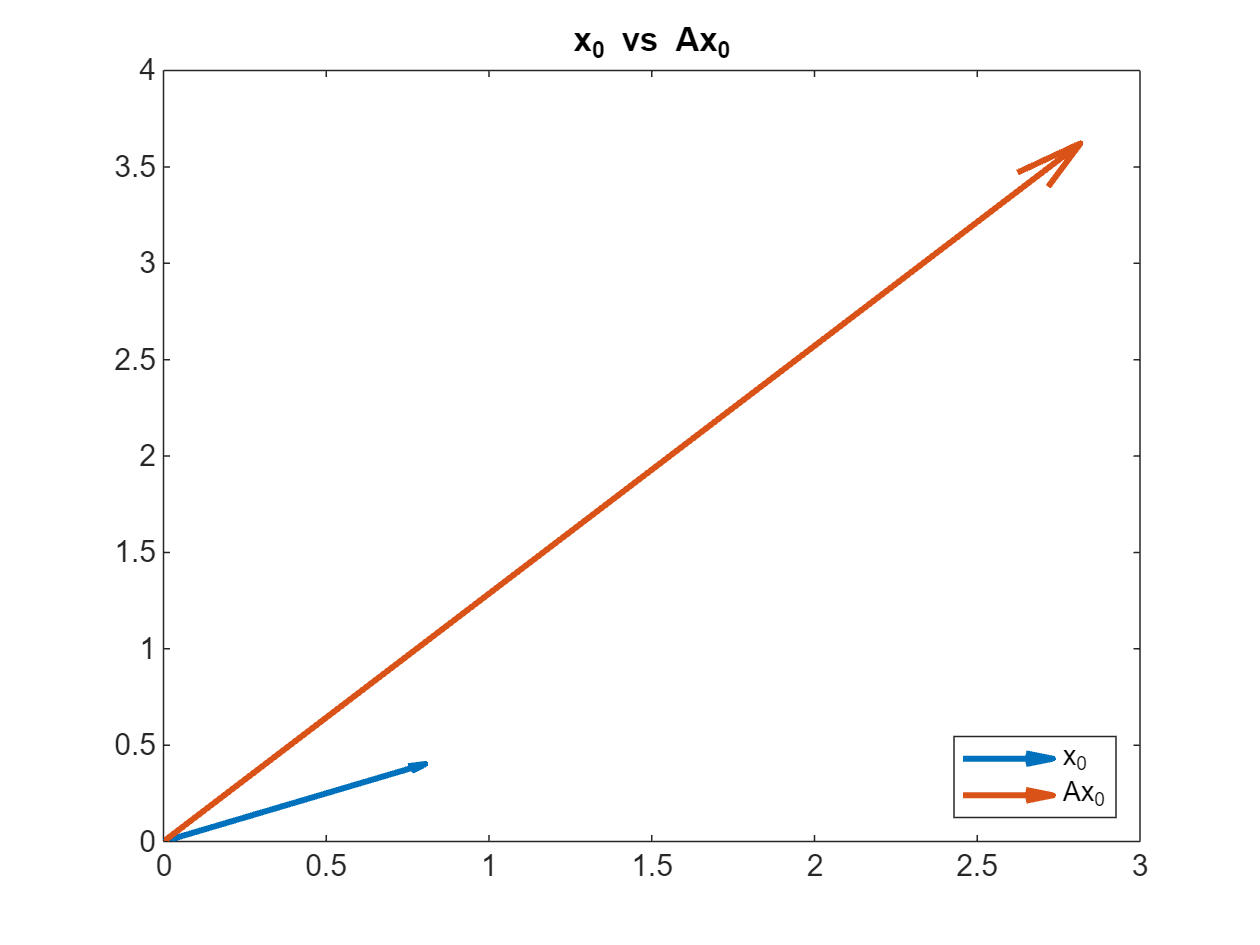

Ax0=A*x0;
quiver(0,0,x0(1,1),x0(2,1),LineWidth=2)
hold on
quiver(0,0,Ax0(1,1),Ax0(2,1),LineWidth=2)
title("x_0 vs Ax_0")
legend("x_0","Ax_0",Location="southeast")
hold off

We'll now plot the resulting vector $x$ or in this case $x_5$ versus $Ax_5$. 

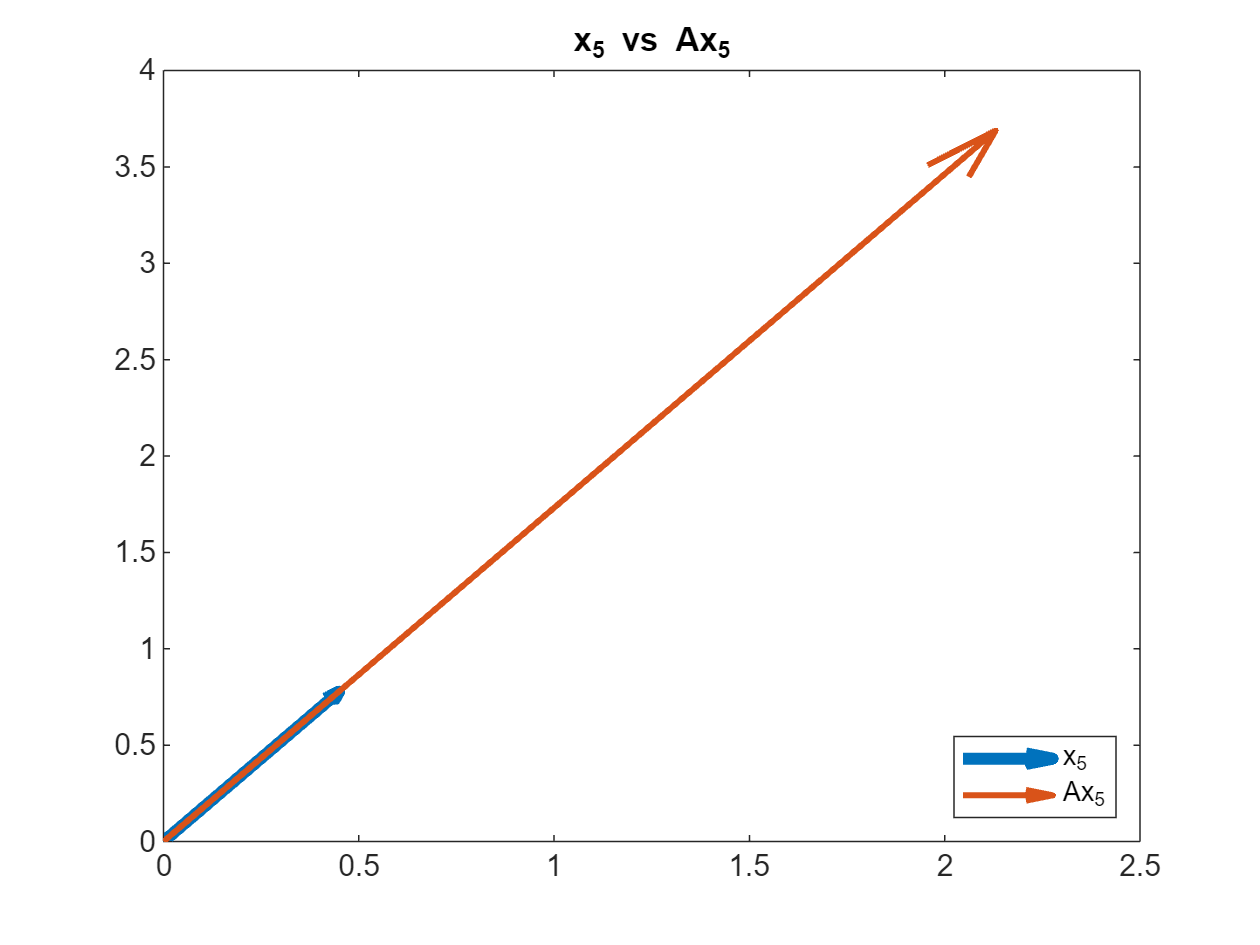

Ax=A*x;
quiver(0,0,x(1,1),x(2,1),LineWidth=4)
hold on
quiver(0,0,Ax(1,1),Ax(2,1),LineWidth=2)
title("x_5 vs Ax_5")
legend('x_5','Ax_5','Location','southeast')
hold off

 **Reflect**.

Notice anything by comparing the two plots? Anything you can say about vector $x_5$? Can you explain the definition of an eigenvector/eigenvalue $\left(\textrm{Ax}=\lambda x\right)$ graphically based on the previous plot? 

Let's now verify that $x_5$ is an eigenvector by using the eig command in MATLAB. Check the MathWorks documentation page for [eig](https://www.mathworks.com/help/matlab/ref/eig.html).

[v,d]=eig(A); % v stores the eigenvectors (in columns), d stores the eigenvalues (in the diagonal elements)
v

v =     0.5000   -0.5000
    0.8660    0.8660


x % re-displaying the output from the previous power iteration

x =     0.5006
    0.8657


Notice how one of the eigenvectors of $A$ (columns of v) is almost identical to vector x.

Now let's calculate the Rayleigh quotient for $x_5$ and display that alongside the eigenvalues of $A$. Check the MathWorks documentation page for [ctranspose](https://www.mathworks.com/help/matlab/ref/ctranspose.html).

rayleigh=ctranspose(x)*A*x

rayleigh = 4.7334

d % displaying the eigenvalues of A for comparison

d =     4.7321         0
         0    1.2679


Notice that one of the diagonal elements of d (dominant eigenvalue) is almost equal to the calculated Rayleigh Quotient.

The Rayleigh quotient is a great way to calculate dominant eigenvalues if vector $x$ is an eigenvector of $A$. And by using the power iteration, we are guaranteed to find a dominant eigenvector.

So we just saw an alternative and very simple way of calculating dominant eigenvalues/eigenvectors for any given square matrix. The caveat here is that we can't calculate all the eigenvalues but only the dominant (largest/smallest) ones. This may sound like a major limitation but for most engineering and real-life problems it suffices.

We'll now explore the same concepts from a performance standpoint. We'll compare calculation speed of eigenvalues/eigenvectors with (i) power iteration, (ii) the eig MATLAB function and finally, (iii) the good old characteristic polynomial approach. We'll test this for a 6x6 matrix. First, let's see how fast power iteration is. Check the MathWorks documentation pages for [tic](https://www.mathworks.com/help/matlab/ref/tic.html) and [toc](https://www.mathworks.com/help/matlab/ref/toc.html) functions.

A=randi(4,6,6);
x0=randi(4,6,1);
x0=x0/norm(x0);
n=1;
x=x0;
tic % starting the timer
while n<11 % running the iteration 10 times
    x=(A*x)/norm(A*x);
    n=n+1;
end
rayleigh=ctranspose(x)*A*x;
time_power_iteration=toc % stopping the timer

time_power_iteration = 0.0042

tic
[v,d]=eig(A);
time_matlab_eig=toc

time_matlab_eig = 0.0059

v % displaying the eigenvectors (columns) for validation

v =    0.4612 + 0.0000i  -0.1848 - 0.1537i  -0.1848 + 0.1537i   0.3752 + 0.0000i  -0.0082 + 0.0000i  -0.0192 + 0.0000i
   0.3890 + 0.0000i   0.3689 - 0.2091i   0.3689 + 0.2091i  -0.2552 + 0.0000i   0.4836 + 0.0000i  -0.7001 + 0.0000i
   0.4968 + 0.0000i   0.0908 + 0.3265i   0.0908 - 0.3265i   0.5819 + 0.0000i  -0.2981 + 0.0000i   0.1124 + 0.0000i
   0.2441 + 0.0000i   0.0405 + 0.2394i   0.0405 - 0.2394i  -0.3013 + 0.0000i   0.5089 + 0.0000i  -0.1597 + 0.0000i
   0.3181 + 0.0000i   0.3019 - 0.3212i   0.3019 + 0.3212i  -0.0275 + 0.0000i  -0.1168 + 0.0000i   0.3901 + 0.0000i
   0.4779 + 0.0000i  -0.6278 + 0.0000i  -0.6278 + 0.0000i  -0.6033 + 0.0000i  -0.6361 + 0.0000i   0.5649 + 0.0000i


d % displaying the eigenvalues (diagonal elements)

d =   16.4484 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -1.7395 + 1.8963i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -1.7395 - 1.8963i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -1.9711 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.8201 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.1817 + 0.0000i


x % displaying the output of power iteration (dominant eigenvector)

x =     0.4612
    0.3890
    0.4968
    0.2441
    0.3181
    0.4779


rayleigh % displaying the rayleigh quotient

rayleigh = 16.4484

Now let's derive the eigenvalues using the characteristic polynomial. Check the MathWorks documentation pages for [syms](https://www.mathworks.com/help/symbolic/syms.html), [charpoly](https://www.mathworks.com/help/symbolic/sym.charpoly.html), [solve](https://www.mathworks.com/help/symbolic/sym.solve.html) and [vpa](https://www.mathworks.com/help/symbolic/vpa.html). VPA stands for variable precision arithmetic and it is used to numerically approximate the default, symbolic output of the solve function.

tic
syms x
charpol = charpoly(A,x);
eigenvalues = vpa(solve(charpol),4);
time_char_poly=toc

time_char_poly = 0.9595

eigenvalues

$$eigenvalues = \left(\begin{array}{c} 0.1817\\ 0.8201\\ -1.971\\ -1.74+1.896\,\mathrm{i}\\ -1.74-1.896\,\mathrm{i}\\ 16.45 \end{array}\right)$$

 **Reflect**.

Which method was faster? Remember that with the eig function we are able to calculate all eigenvalues and eigenvectors. Previous findings should give you an idea why numerical linear algebra techniques and algorithms are important.

   **Try**

Write your own code below and test calculation speed for $n>6$. You can use a dropdown menu and experiment with multiple, large values for $n$. A short video on how to integrate live controls in your code can be found [here](https://www.mathworks.com/videos/how-to-use-live-editor-controls-1569868241587.html).

## **Further exploration**

Finding eigenvalues by calculating the characteristic polynomial comes down to finding roots. And polynomial roots can be very sensitive to perturbations (minor changes) in the polynomial coefficients. In real-life applications, it often happens that we don't have 100% accurate parameter estimation and this practically translates to some inaccuracies in the characteristic polynomial coefficients. Therefore, the characteristic polynomial is not very reliable if we want to approximate eigenvalues in a practical scenario.

MathWorks' chief mathematician and co-founder, Cleve Moler, wrote about this in his blog 11 years ago: [Cleve's Corner: Wilkinson's Polynomials](https://blogs.mathworks.com/cleve/2013/03/04/wilkinsons-polynomials/). It's an interesting read if you are willing to dig a little deeper. Specifically in the Wilkinson's perturbation section, he talks about what happens if we change one polynomial coefficient by a tiny little bit ($2^{-k} ,23\le k\le 36$).

## **Practice problem**

Write code that calculates dominant eigenvalues/eigenvectors with the use of power iteration for a random 6x6 matrix and terminates when $\left|R\left(A,x_k \right)-R\left(A,x_{k-1} \right)\right|\le \varepsilon R\left(A,x_k \right)$ and $\left\|x_k -x_{k-1} \right\|\le \varepsilon$ for an arbitrarily small $\varepsilon$ of your choice. 

-     Test for larger dimensions and multiple values for $\varepsilon$ and confirm it's working properly by comparing the results with the eig function. Comment on the number of iterations we need for the algorithm to converge.

-     Run your code for the inverse matrix $A^{-1}$. Were the outputs expected?

For this practice problem, check MathWorks documentation pages for [abs](https://www.mathworks.com/help/matlab/ref/abs.html), [if](https://www.mathworks.com/help/matlab/ref/if.html), [inv](https://www.mathworks.com/help/matlab/ref/inv.html) and [mldivide](https://www.mathworks.com/help/matlab/ref/double.mldivide.html) (otherwise known as the MATLAB backslash).

  **Pro-tip.**

This script focuses on numerical linear algebra techniques and we'd like to close with a pro tip. You are probably wondering what's with the mldivide function? Mldivide (or backslash) is used to solve a linear system $\mathrm{Ax}=B$ and it's one of our flagship functions, because it's fast and efficient. There's a way to use the backslash ($x=A\backslash B$) and calculate the inverse of a matrix. That part is left to you as a short exercise. You can use the inv function for the practice problem above if you so wish, but our recommendation is to make use of the backslash.